# Franka Emika Panda Singularities Set 2

clc; clear; close;

#### Define the transformation matrices for the Franka Emika Panda Robot / Configuration 2

M = [[1, 0, 0, 0.088];[0, -1, 0, 0];[0, 0, -1, 0.926];[0, 0, 0, 1]];
vpa(M, 4);
S = [[0;0;1;0;0;0],[0;1;0;-0.333;0;0],[0;0;1;0;0;0],[0;-1;0;0.316+0.333;0;-0.0825],[0;0;1;0;0;0],[0;-1;0;0.384+0.316+0.333;0;0],[0;0;-1;0;0.088;0]];
vpa(S, 4);

#### Defining joint limits 

qlim = [-2.8973, 2.8973; -1.7628, 1.7628; -2.8973, 2.8973; -3.0718, -0.0698; -2.8973, 2.8973; -0.0175, 3.7525; -2.8973, 2.8973];

vpa(qlim, 5)

$$ans = \left(\begin{array}{cc} -2.8973 & 2.8973\\ -1.7628 & 1.7628\\ -2.8973 & 2.8973\\ -3.0718 & -0.0698\\ -2.8973 & 2.8973\\ -0.0175 & 3.7525\\ -2.8973 & 2.8973 \end{array}\right)$$

#### Generate a set of discrete joint angles within the joint limits

for i=1:size(qlim, 1)
    Qlim(i, :) = linspace(qlim(i, 1), qlim(i, 2), 10);
end
Qlim

Qlim =    -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -1.7628   -1.3711   -0.9793   -0.5876   -0.1959    0.1959    0.5876    0.9793    1.3711    1.7628
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -3.0718   -2.7382   -2.4047   -2.0711   -1.7376   -1.4040   -1.0705   -0.7369   -0.4034   -0.0698
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973
   -0.0175    0.4014    0.8203    1.2392    1.6581    2.0769    2.4958    2.9147    3.3336    3.7525
   -2.8973   -2.2535   -1.6096   -0.9658   -0.3219    0.3219    0.9658    1.6096    2.2535    2.8973


#### **Solving Singularity equation with DH Parameters**

a1 = 0; a2 = 0; a3 = 0; a4 = 0.0825;
a5 = -0.0825; a6 = 0; a7 = 0.088; aF = 0;
d1 = 0.333; d2 = 0; d3 = 0.316; d4 = 0;
d5 = 0.384; d6 = 0; d7 = 0; dF = 0.107;
syms th4
syms th6
eq = cos(th4)*a5*[a7+(d3+d5)*sin(th6)] + sin(th4)*[-a7*d3 + (a5^2 - d5*d3)*sin(th6)]==0;
vpa(eq,4)

$$ans = -0.0825\,\cos\left({\mathrm{th}}_{4}\right)\,\left(0.7\,\sin\left({\mathrm{th}}_{6}\right)+0.088\right)-1.0\,\sin\left({\mathrm{th}}_{4}\right)\,\left(0.1145\,\sin\left({\mathrm{th}}_{6}\right)+0.02781\right)=0.0$$

f=@(th4,th6) cos(th4)*a5*[a7+(d3+d5)*sin(th6)] + sin(th4)*[-a7*d3 + (a5^2 - d5*d3)*sin(th6)];
fimplicit(f,[-176/180*pi -4/180*pi -1/180*pi 215/180*pi])

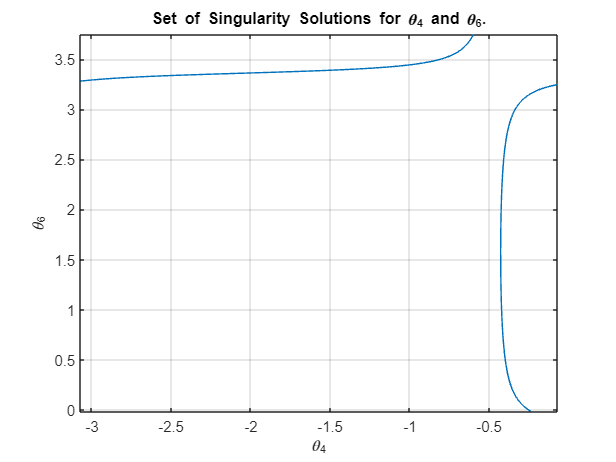

title('Set of Singularity Solutions for \theta_4 and \theta_6.');
xlabel('\theta_4');
ylabel('\theta_6');
grid on;

#### We have a lot of sets of $\theta_4$ and $\theta_6$, which satisfy the singularity equation.

#### To simplify, we choose only two sets. 

#### The first set is: $\theta_4 = -2$ and $\theta_6 = 3.36426$

th4 = -2;
S_eq1 = vpa(solve(cos(th4)*a5*[a7+(d3+d5)*sin(th6)] + sin(th4)*[-a7*d3 + (a5^2 - d5*d3)*sin(th6)]==0,th6),10)

$$S\_eq1 = \left(\begin{array}{c} -0.2226708285\\ 3.364263482 \end{array}\right)$$

#### For $\theta_4 = -0.4$ we have two sets of answer for $\theta_6$ that are within the Joint limits.

#### To simplify, we choose $\theta_6 = 0.5033$.

th4 = -0.4;
S_eq2 = vpa(solve(cos(th4)*a5*[a7+(d3+d5)*sin(th6)] + sin(th4)*[-a7*d3 + (a5^2 - d5*d3)*sin(th6)]==0,th6),10)

$$S\_eq2 = \left(\begin{array}{c} 0.50327402\\ 2.638318634 \end{array}\right)$$

#### Define Singular Configurations (Define all possible configs for first set of solution) 

Q1 = Qlim(1, :);
Q2 = Qlim(2, :);
Q3 = Qlim(3, :);
Q4 = [-2];
Q5 = [pi/2, -pi/2];
Q6 = [S_eq1(2)];
Q7 = Qlim(7, :);

#### Generate all possible combinations of joint angles for the robot

Q = unique(combvec(Q1, Q2, Q3, Q4, Q5, Q6, Q7)', 'rows');
Q

Q =    -2.8973   -1.7628   -2.8973   -2.0000   -1.5708    3.3643   -2.8973
   -2.8973   -1.7628   -2.8973   -2.0000   -1.5708    3.3643   -2.2535
   -2.8973   -1.7628   -2.8973   -2.0000   -1.5708    3.3643   -1.6096
   -2.8973   -1.7628   -2.8973   -2.0000   -1.5708    3.3643   -0.9658
   -2.8973   -1.7628   -2.8973   -2.0000   -1.5708    3.3643   -0.3219
   -2.8973   -1.7628   -2.8973   -2.0000   -1.5708    3.3643    0.3219
   -2.8973   -1.7628   -2.8973   -2.0000   -1.5708    3.3643    0.9658
   -2.8973   -1.7628   -2.8973   -2.0000   -1.5708    3.3643    1.6096
   -2.8973   -1.7628   -2.8973   -2.0000   -1.5708    3.3643    2.2535
   -2.8973   -1.7628   -2.8973   -2.0000   -1.5708    3.3643    2.8973


#### Remove duplicate joint angles

uniqueQ = unique(Q, 'rows');
numDuplicates = size(Q,1) - size(uniqueQ,1)

numDuplicates = 0

####  Compute the forward kinematics for each unique set of joint angles

for i = 1:size(uniqueQ,1)
    T1 = FK_SpaceForm(S, M, uniqueQ(i, 1: 7)');
    X(i) = T1(1, 4);
    Y(i) = T1(2, 4);
    Z(i) = T1(3, 4);
end

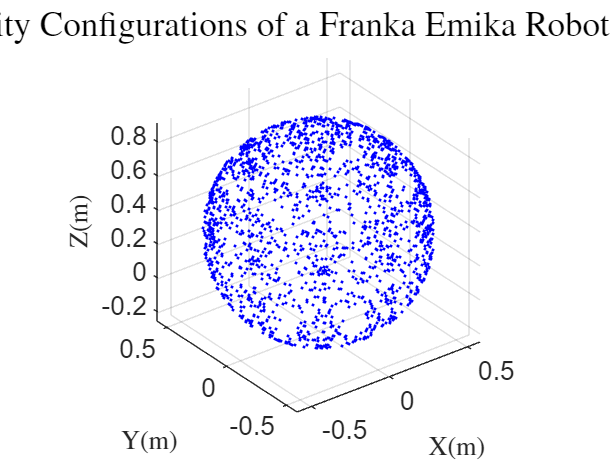

%distance = sqrt(X.^2 + Y.^2 + Z.^2); % compute distance from origin
%c = distance/max(distance); % normalize distances to [0,1]

scatter3(X, Y, Z, 'b.');
% colormap jet; % set the color map
% colorbar; % add a color bar to the plot
ax = gca;
ax.FontSize = 18;
xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');
title('Singularity Configurations of a Franka Emika Robot (Config 2)', 'FontSize', 24, 'Interpreter','latex');
axis equal;

%view(0,0);

#### Choose an arbitrary config to visualize

Q1_rndm = Q1(randi(numel(Q1)));
Q2_rndm = Q2(randi(numel(Q2)));
Q3_rndm = Q3(randi(numel(Q3)));
Q4_rndm = [-2];
Q5_rndm = [pi/2, -pi/2];
Q6_rndm = [S_eq1(2)];
Q7_rndm = Q7(randi(numel(Q7)));

thetas = unique(combvec(Q1_rndm, Q2_rndm, Q3_rndm, Q4_rndm, Q5_rndm, Q6_rndm, Q7_rndm)', 'rows');
thetas

thetas =     0.3219    0.1959    2.2535   -2.0000   -1.5708    3.3643   -2.2535
    0.3219    0.1959    2.2535   -2.0000    1.5708    3.3643   -2.2535


Js =          0   -0.3164    0.1846    0.5224   -0.8338   -0.1786   -0.9286
         0    0.9486    0.0616    0.8392    0.4656    0.2808    0.2688
    1.0000         0    0.9809   -0.1510   -0.2966    0.9430   -0.2559
         0   -0.3159   -0.0205   -0.5578   -0.3662    0.0776   -0.2182
         0   -0.1054    0.0615    0.3396   -0.6169    0.2154   -0.6860
         0         0         0   -0.0421    0.0610   -0.0495    0.0712


ans = 5

2 linearly dependent joints:
  q6 depends on: q1 q2 q3 q5 
  q7 depends on: q1 q2 q3 q4 q5 


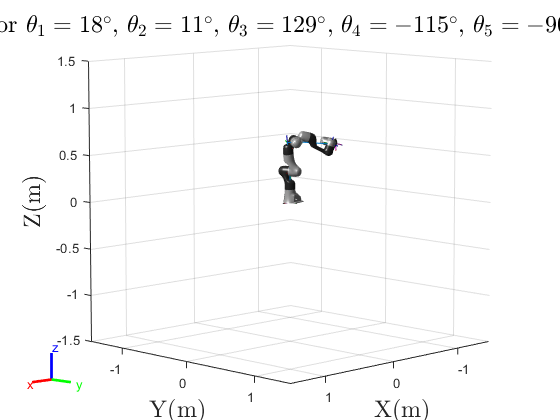

Js =          0   -0.3164    0.1846    0.5224   -0.8338    0.1786   -0.6979
         0    0.9486    0.0616    0.8392    0.4656   -0.2808    0.6395
    1.0000         0    0.9809   -0.1510   -0.2966   -0.9430   -0.3226
         0   -0.3159   -0.0205   -0.5578   -0.3662   -0.0776   -0.4961
         0   -0.1054    0.0615    0.3396   -0.6169   -0.2154   -0.5173
         0         0         0   -0.0421    0.0610    0.0495    0.0478


ans = 5

2 linearly dependent joints:
  q6 depends on: q1 q2 q3 q5 
  q7 depends on: q1 q2 q3 q4 q5 


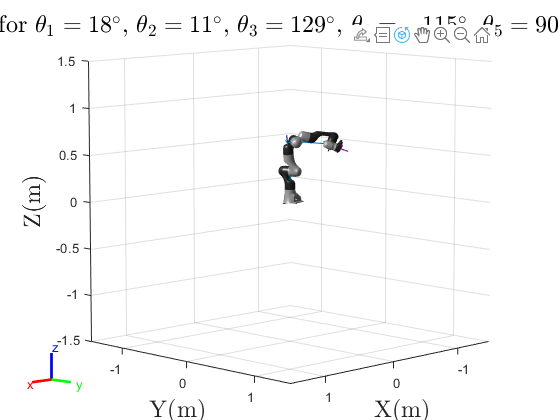


for theta = thetas'
    Js = J_SpaceForm(S, theta)
    rank(Js)
    jsingu(Js)
    robot = importrobot('Franka_Emika_Panda.urdf');
    robot.DataFormat = 'column';

    figure;

    str = "Singular Configuration for ";
    for i= 1:numel(theta)
        str = str + "$\theta_" + num2str (i) + "=" +num2str(round(rad2deg(theta(i)))) + "^ \circ $, ";
    end

    show(robot,theta,'Visuals','on','Frames','on');
    xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
    ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
    zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');

    title(str, 'FontSize', 18, 'Interpreter','latex');

end

#### Define Singular Configurations (Define all possible configs for Second set of solution) 

Q1 = Qlim(1, :);
Q2 = Qlim(2, :);
Q3 = Qlim(3, :);
Q4 = [-0.4];
Q5 = [pi/2, -pi/2];
Q6 = [S_eq2(1)];
Q7 = Qlim(7, :);

#### Generate all possible combinations of joint angles for the robot

Q = unique(combvec(Q1, Q2, Q3, Q4, Q5, Q6, Q7)', 'rows');
Q

Q =    -2.8973   -1.7628   -2.8973   -0.4000   -1.5708    0.5033   -2.8973
   -2.8973   -1.7628   -2.8973   -0.4000   -1.5708    0.5033   -2.2535
   -2.8973   -1.7628   -2.8973   -0.4000   -1.5708    0.5033   -1.6096
   -2.8973   -1.7628   -2.8973   -0.4000   -1.5708    0.5033   -0.9658
   -2.8973   -1.7628   -2.8973   -0.4000   -1.5708    0.5033   -0.3219
   -2.8973   -1.7628   -2.8973   -0.4000   -1.5708    0.5033    0.3219
   -2.8973   -1.7628   -2.8973   -0.4000   -1.5708    0.5033    0.9658
   -2.8973   -1.7628   -2.8973   -0.4000   -1.5708    0.5033    1.6096
   -2.8973   -1.7628   -2.8973   -0.4000   -1.5708    0.5033    2.2535
   -2.8973   -1.7628   -2.8973   -0.4000   -1.5708    0.5033    2.8973


#### Remove duplicate joint angles

uniqueQ = unique(Q, 'rows');
numDuplicates = size(Q,1) - size(uniqueQ,1)

numDuplicates = 0

####  Compute the forward kinematics for each unique set of joint angles

for i = 1:size(uniqueQ,1)
    T1 = FK_SpaceForm(S, M, uniqueQ(i, 1: 7)');
    X(i) = T1(1, 4);
    Y(i) = T1(2, 4);
    Z(i) = T1(3, 4);
end

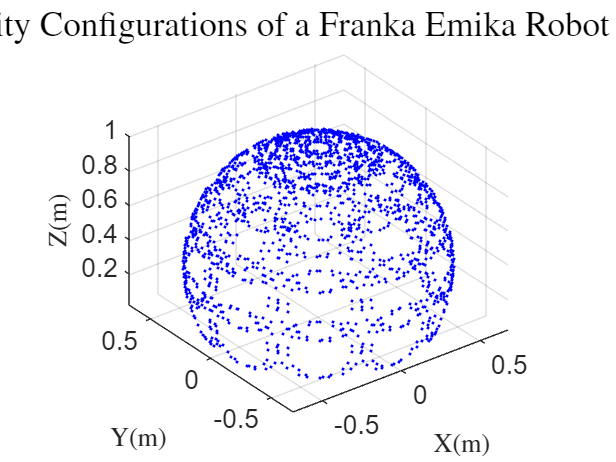

%distance = sqrt(X.^2 + Y.^2 + Z.^2); % compute distance from origin
%c = distance/max(distance); % normalize distances to [0,1]
figure
scatter3(X, Y, Z, 'b.');
% colormap jet; % set the color map
% colorbar; % add a color bar to the plot
ax = gca;
ax.FontSize = 18;
xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');
title('Singularity Configurations of a Franka Emika Robot (Config 2)', 'FontSize', 24, 'Interpreter','latex');
axis equal;

%view(0,0);

#### Choose an arbitrary config to visualize

Q1_rndm = Q1(randi(numel(Q1)));
Q2_rndm = Q2(randi(numel(Q2)));
Q3_rndm = Q3(randi(numel(Q3)));
Q4_rndm = [-0.4];
Q5_rndm = [pi/2, -pi/2];
Q6_rndm = [S_eq2(1)];
Q7_rndm = Q7(randi(numel(Q7)));

thetas = unique(combvec(Q1_rndm, Q2_rndm, Q3_rndm, Q4_rndm, Q5_rndm, Q6_rndm, Q7_rndm)', 'rows');
thetas

thetas =    -2.2535   -1.3711   -0.9658   -0.4000   -1.5708    0.5033   -0.3219
   -2.2535   -1.3711   -0.9658   -0.4000    1.5708    0.5033   -0.3219


Js =          0    0.7759    0.6183   -0.3384    0.2933    0.8941   -0.4201
         0   -0.6309    0.7605    0.4854    0.8684   -0.1011   -0.5266
    1.0000         0    0.1984   -0.8061    0.3998   -0.4362   -0.7391
         0    0.2101   -0.2532   -0.4368   -0.2453   -0.2056   -0.2284
         0    0.2584    0.2059   -0.0391    0.0348    0.6410    0.0129
         0         0         0    0.1598    0.1044   -0.5701    0.1207


ans = 5

2 linearly dependent joints:
  q6 depends on: q1 q2 q3 q5 
  q7 depends on: q1 q2 q3 q4 q5 


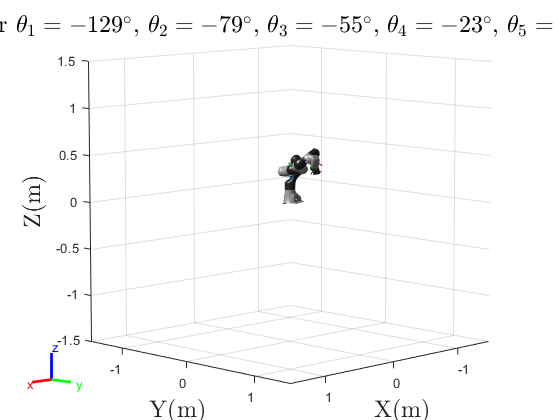

Js =          0    0.7759    0.6183   -0.3384    0.2933   -0.8941   -0.0937
         0   -0.6309    0.7605    0.4854    0.8684    0.1011   -0.9949
    1.0000         0    0.1984   -0.8061    0.3998    0.4362    0.0385
         0    0.2101   -0.2532   -0.4368   -0.2453    0.2056    0.6582
         0    0.2584    0.2059   -0.0391    0.0348   -0.6410   -0.0738
         0         0         0    0.1598    0.1044    0.5701   -0.3036


ans = 5

2 linearly dependent joints:
  q6 depends on: q1 q2 q3 q5 
  q7 depends on: q1 q2 q3 q4 q5 


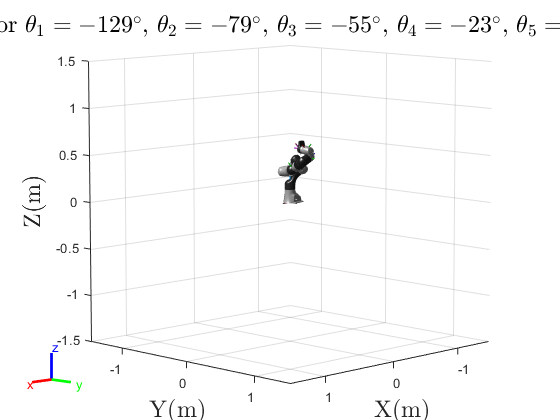


for theta = thetas'
    Js = J_SpaceForm(S, theta)
    rank(Js)
    jsingu(Js)
    robot = importrobot('Franka_Emika_Panda.urdf');
    robot.DataFormat = 'column';

    figure;

    str = "Singular Configuration for ";
    for i= 1:numel(theta)
        str = str + "$\theta_" + num2str (i) + "=" +num2str(round(rad2deg(theta(i)))) + "^ \circ $, ";
    end

    show(robot,theta,'Visuals','on','Frames','on');
    xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
    ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
    zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');

    title(str, 'FontSize', 18, 'Interpreter','latex');

end